# Evaluación de las capacidades de robot Scara

% Definicion de los puntos (TRAYECTORIA PERSONALIZADA - BARRIDO AMPLIO)

% Pose inicial (Cuadrante Positivo Y, girado -45 grados)
x_in = 0.6;       % Reducimos un poco X para ganar rango en Y
y_in = 0.5;       % Empezamos más "arriba"
theta_in = -pi/4; % Orientación inicial inclinada (-0.78 rad)

% Pose final (Cuadrante Negativo Y, girado +45 grados)
x_fin = 0.6;      % Mantenemos X constante (movimiento vertical principal)
y_fin = -0.5;     % Terminamos "abajo" (simétrico)
theta_fin = pi/4; % Orientación final opuesta (+0.78 rad)

### Definición de la tarea en el espacio de las juntas

% Cálculo de la solución de la primer postura

% Definición de los parámetros del robot
L1 = 0.45; % Longitud del primer eslabón en base al URDF de robot scara
L2 = 0.45; % Longitud del segundo eslabón eslabón en base al URDF de robot scara
L3 = 0.25; % Longitud del tercer eslabón eslabón en base al URDF de robot scara

% Planteamiento de la solucion

x_3 = x_in - L3*cos(theta_in);
y_3 = y_in - L3*sin(theta_in);

% Solucion por le metodo geometrico

theta_2_in = acos((x_3^2+y_3^2-L1^2-L2^2)/(2*L1*L2));

beta = atan2(y_3,x_3);

psi = acos((x_3^2+y_3^2+L1^2-L2^2)/(2*L1*sqrt(x_3^2+y_3^2)));

theta_1_in = beta + psi;

% theta_1_in = beta - psi

theta_3_in = theta_in -theta_1_in - theta_2_in;


%%%
%% Solucion para el punto final


x_3 = x_fin - L3*cos(theta_fin);
y_3 = y_fin - L3*sin(theta_fin);

% Solucion por le metodo geometrico

theta_2_fin = acos((x_3^2+y_3^2-L1^2-L2^2)/(2*L1*L2));

beta = atan2(y_3,x_3);

psi = acos((x_3^2+y_3^2+L1^2-L2^2)/(2*L1*sqrt(x_3^2+y_3^2)));

theta_1_fin = beta + psi;

% theta_1_fin = beta - psi

theta_3_fin = theta_fin -theta_1_fin - theta_2_fin;



### Planteamiento de una trayectoria en el espacio de las juntas del robot

Definición de la trayectoria


$$q =q_i +\lambda \left(t\right)\left(q_{\textrm{fin}} -q_{\textrm{in}} \right)$$


tf = 8;



for i=1:tf+1
    t = i-1; % Increment time for the next iteration
    theta_1_P(i) = theta_1_in + ((10/tf^3)*t^3 - (15/tf^4)*t^4 + (6/tf^5)*t^5)*(theta_1_fin-theta_1_in);
    theta_2_P(i) = theta_2_in + ((10/tf^3)*t^3 - (15/tf^4)*t^4 + (6/tf^5)*t^5)*(theta_2_fin-theta_2_in);
    theta_3_P(i) = theta_3_in + ((10/tf^3)*t^3 - (15/tf^4)*t^4 + (6/tf^5)*t^5)*(theta_3_fin-theta_3_in);
    
end



### Planeación de trayectoria en el espacio de trabajo del robot

% Cálculo de la solución de la primer postura

% Definición de los parámetros del robot
L1 = 0.45; % Longitud del primer eslabón en base al URDF del robot scara
L2 = 0.45; % Longitud del segundo eslabón en base al URDF del robot scara
L3 = 0.25; % Longitud del tercer eslabón en base al URDF del robot scara


% x_in = 0.3;
% y_in = 0.3;
% theta_in = 0; 

% x_fin = 0.3;
%y_fin = -0.3;
% theta_fin = pi/2;

tf = 8;
for i=1:tf+1
    t = i-1;
    x_P(i) = x_in + ((10/tf^3)*t^3 - (15/tf^4)*t^4 + (6/tf^5)*t^5)*(x_fin-x_in);
    y_P(i) = y_in + ((10/tf^3)*t^3 - (15/tf^4)*t^4 + (6/tf^5)*t^5)*(y_fin-y_in);
    theta_P(i) = theta_in + ((10/tf^3)*t^3 - (15/tf^4)*t^4 + (6/tf^5)*t^5)*(theta_fin-theta_in);

    x_3_a(i) = x_P(i) - L3*cos(theta_P(i));
    y_3_a(i) = y_P(i) - L3*sin(theta_P(i));

    % Solucion por le metodo geometrico

    theta_2_tray(i) = acos((x_3_a(i)^2+y_3_a(i)^2-L1^2-L2^2)/(2*L1*L2));

    beta = atan2(y_3_a(i),x_3_a(i));

    psi = acos((x_3_a(i)^2+y_3_a(i)^2+L1^2-L2^2)/(2*L1*sqrt(x_3_a(i)^2+y_3_a(i)^2)));

    theta_1_tray(i) = beta + psi;

    % theta_1_in = beta - psi

    theta_3_tray(i) = theta_P(i) - theta_1_tray(i) - theta_2_tray(i);

end


tsim=0:1:tf

tsim =      0     1     2     3     4     5     6     7     8


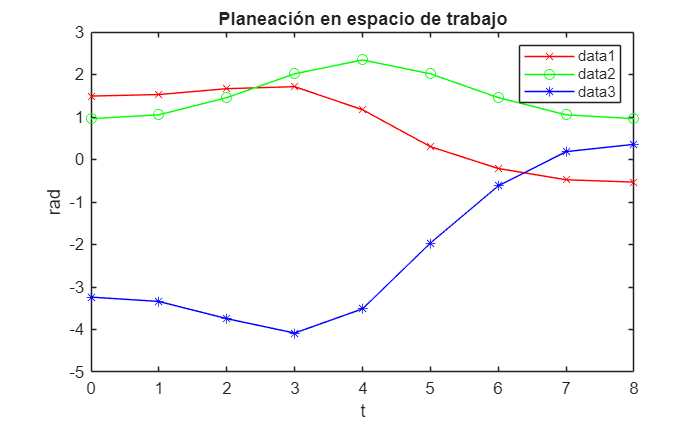

figure;

plot(tsim, theta_1_tray, 'r-x');
hold on;
plot(tsim, theta_2_tray, 'g-o');
plot(tsim, theta_3_tray, 'b-*');

hold off;

legend
title("Planeación en espacio de trabajo")
xlabel("t")
ylabel("rad")

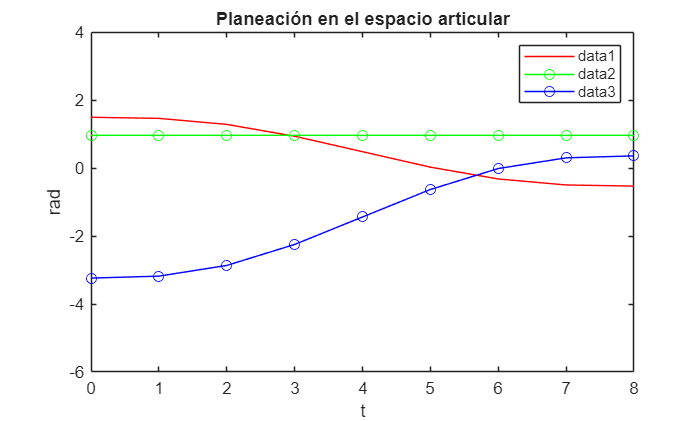




figure;

plot(tsim, theta_1_P, 'r-');
hold on;
plot(tsim, theta_2_P, 'g-o');
plot(tsim, theta_3_P, 'b-o');

hold off;

xlim([0.00 8.00])
ylim([-6.0 4.0])
legend
title("Planeación en el espacio articular")
xlabel("t")
ylabel("rad")


% w = L1*L2*sin(theta_2)

### Calculo de la cinemática de velocidades del robot

### **Cinemática de velocidades en espacio de las juntas**

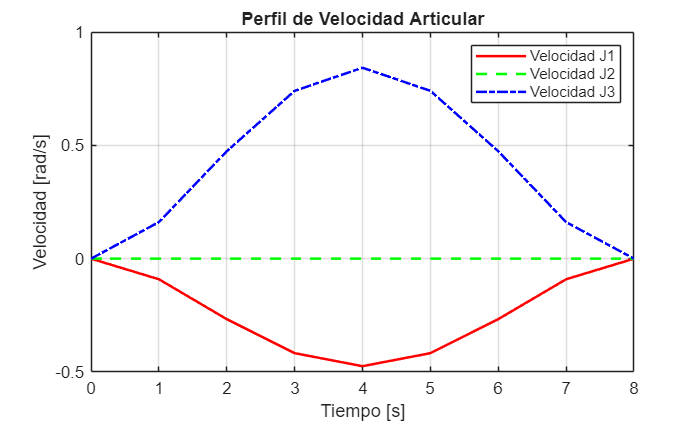

tf = 8;

% Inicializar vectores para velocidad 
theta_1_P_v = zeros(1, tf+1);
theta_2_P_v = zeros(1, tf+1);
theta_3_P_v = zeros(1, tf+1);

for i = 1 : tf + 1
    t = i - 1; % Empezar en t=0
    
    % Polinomio de Velocidad (Derivada del de posición)
    poly_vel = (30/tf^3)*t^2 - (60/tf^4)*t^3 + (30/tf^5)*t^4;
    
    theta_1_P_v(i) = poly_vel * (theta_1_fin - theta_1_in);
    theta_2_P_v(i) = poly_vel * (theta_2_fin - theta_2_in);
    theta_3_P_v(i) = poly_vel * (theta_3_fin - theta_3_in);
end

% --- GRÁFICA MEJORADA ---
figure;
plot(tsim, theta_1_P_v, 'r-', 'LineWidth', 1.5); hold on;
plot(tsim, theta_2_P_v, 'g--', 'LineWidth', 1.5);
plot(tsim, theta_3_P_v, 'b-.', 'LineWidth', 1.5);
hold off;

% Etiquetas y Títulos
title('Perfil de Velocidad Articular'); 
xlabel('Tiempo [s]'); 
ylabel('Velocidad [rad/s]'); 
legend('Velocidad J1', 'Velocidad J2', 'Velocidad J3'); 
grid on;

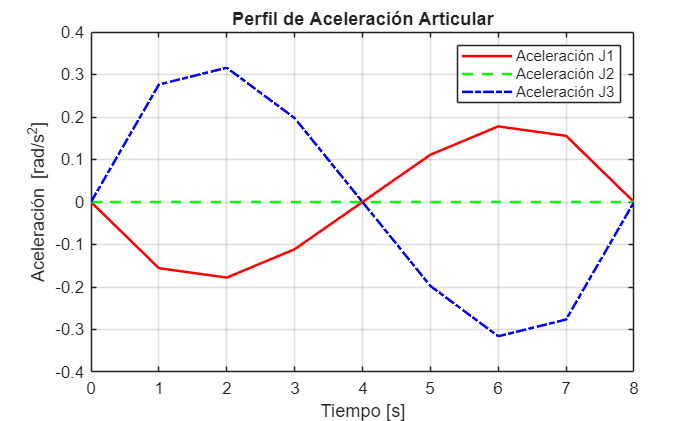

tf = 8;

% Inicializar vectores para aceleración 
theta_1_P_a = zeros(1, tf+1);
theta_2_P_a = zeros(1, tf+1);
theta_3_P_a = zeros(1, tf+1);

for i = 1 : tf + 1
    t = i - 1; % Empezar en t=0
    
    % Polinomio de Aceleración (Segunda derivada del de posición)
    poly_accel = (60/tf^3)*t - (180/tf^4)*t^2 + (120/tf^5)*t^3;
    
    theta_1_P_a(i) = poly_accel * (theta_1_fin - theta_1_in);
    theta_2_P_a(i) = poly_accel * (theta_2_fin - theta_2_in);
    theta_3_P_a(i) = poly_accel * (theta_3_fin - theta_3_in);
end

% --- GRÁFICA MEJORADA (ACELERACIÓN) ---
figure;
plot(tsim, theta_1_P_a, 'r-', 'LineWidth', 1.5); hold on;
plot(tsim, theta_2_P_a, 'g--', 'LineWidth', 1.5);
plot(tsim, theta_3_P_a, 'b-.', 'LineWidth', 1.5);
hold off;

% Etiquetas y Títulos 
title('Perfil de Aceleración Articular'); 
xlabel('Tiempo [s]'); 
ylabel('Aceleración [rad/s^2]'); 
legend('Aceleración J1', 'Aceleración J2', 'Aceleración J3'); 
grid on;

### **Cinemática de velocidades en espacio de trabajo**

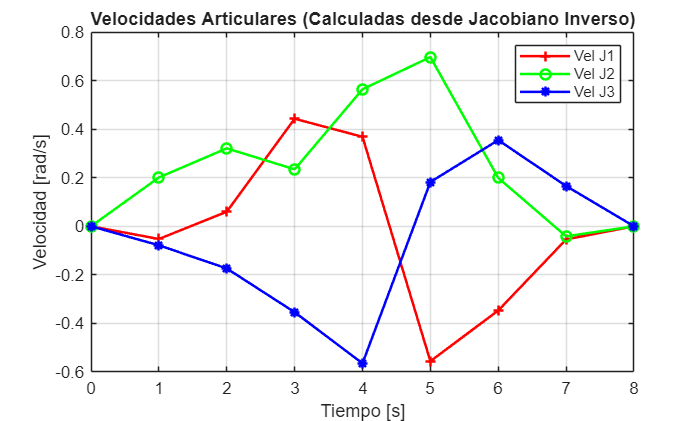

%% CINEMÁTICA DE VELOCIDADES EN ESPACIO DE TRABAJO (JACOBIANO INVERSO)

% 1. Definición de parámetros reales (robot SCARA)
L_1 = 0.45; 
L_2 = 0.45; 
L_3 = 0.25;

% Definir tiempo (Aseguramos que sea el mismo de arriba)
tf = 8; 

% Inicializar vectores 
x_P_v = zeros(1, tf+1);
y_P_v = zeros(1, tf+1);
theta_P_v = zeros(1, tf+1);
theta_1_v = zeros(1, tf+1);
theta_2_v = zeros(1, tf+1);
theta_3_v = zeros(1, tf+1);

% 2. Bucle de Cálculo
for i = 1 : tf + 1
    t = i - 1; % Empezar en 0
    
    % Velocidades Cartesianas Deseadas (Derivada del Polinomio)
    poly_vel = (30/tf^3)*t^2 - (60/tf^4)*t^3 + (30/tf^5)*t^4;
    
    x_P_v(i) = poly_vel * (x_fin - x_in);
    y_P_v(i) = poly_vel * (y_fin - y_in);
    theta_P_v(i) = poly_vel * (theta_fin - theta_in);

    x_dot = x_P_v(i);
    y_dot = y_P_v(i);
    theta_dot_P = theta_P_v(i);
    
    % Recuperar ángulos de la trayectoria cartesiana (Calculados previamente)
    theta_O_1 = theta_1_tray(i);
    theta_1_2 = theta_2_tray(i);
    theta_2_3 = theta_3_tray(i);

    % --- ECUACIONES DEL JACOBIANO INVERSO ---
    % J1
    term1 = (x_dot * cos(theta_1_2 + theta_O_1)) / (L_1 * sin(theta_1_2));
    term2 = (y_dot * sin(theta_1_2 + theta_O_1)) / (L_1 * sin(theta_1_2));
    term3 = (L_3 * theta_dot_P * sin(theta_2_3)) / (L_1 * sin(theta_1_2));
    theta_1_v(i) = term1 + term2 + term3;
    
    % J2 (Fórmula larga )
    num_A = x_dot * (L_2 * cos(theta_1_2 + theta_O_1) + L_1 * cos(theta_O_1));
    num_B = y_dot * (L_2 * sin(theta_1_2 + theta_O_1) + L_1 * sin(theta_O_1));
    num_C = L_3 * theta_dot_P * (L_1 * sin(theta_1_2 + theta_2_3) + L_2 * sin(theta_2_3));
    den = L_1 * L_2 * sin(theta_1_2);
    
    theta_2_v(i) = -(num_A / den) - (num_B / den) - (num_C / den);
    
    % J3
    term_J3_1 = (theta_dot_P * (L_3 * sin(theta_1_2 + theta_2_3) + L_2 * sin(theta_1_2))) / (L_2 * sin(theta_1_2));
    term_J3_2 = (x_dot * cos(theta_O_1)) / (L_2 * sin(theta_1_2));
    term_J3_3 = (y_dot * sin(theta_O_1)) / (L_2 * sin(theta_1_2));
    
    theta_3_v(i) = term_J3_1 + term_J3_2 + term_J3_3;
end

% 3. Gráfica Mejorada
figure;
plot(tsim, theta_1_v, 'r-+', 'LineWidth', 1.5); hold on;
plot(tsim, theta_2_v, 'g-o', 'LineWidth', 1.5);
plot(tsim, theta_3_v, 'b-*', 'LineWidth', 1.5);
hold off;

title('Velocidades Articulares (Calculadas desde Jacobiano Inverso)');
xlabel('Tiempo [s]');
ylabel('Velocidad [rad/s]');
legend('Vel J1', 'Vel J2', 'Vel J3');
grid on;

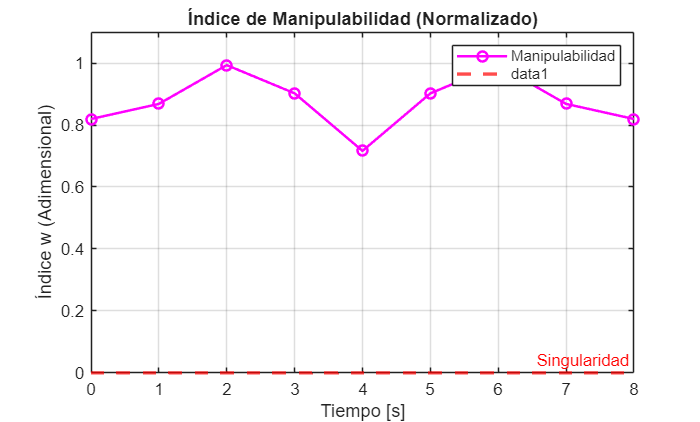

% --- CÁLCULO DE MANIPULABILIDAD ---

% Inicializar vector 
w = zeros(1, tf+1);

for i = 1 : tf + 1
    % Calculamos la manipulabilidad (w = |det(J)|)
    % Nota: Usamos abs() porque la manipulabilidad es una magnitud (siempre positiva)
    % La formula original dividía entre (L1*L2), es una manipulabilidad normalizada (0 a 1)
    w(i) = abs(sin(theta_2_tray(i))); 
end

% --- GRÁFICA MEJORADA ---
figure;
plot(tsim, w, 'm-o', 'LineWidth', 1.5); 
hold off;

% Etiquetas profesionales
title('Índice de Manipulabilidad (Normalizado)');
xlabel('Tiempo [s]');
ylabel('Índice w (Adimensional)');
legend('Manipulabilidad');

% Límites y referencias visuales
ylim([0 1.1]); % Para que se vea bien el rango de 0 a 1
yline(0, 'r--', 'Singularidad', 'LineWidth', 2); % Línea roja en 0 para marcar peligro donde no queremos que el robot llegue
grid on;

### Evaluación de la capacidad del robot

### **Cálculo de los pares del robot**

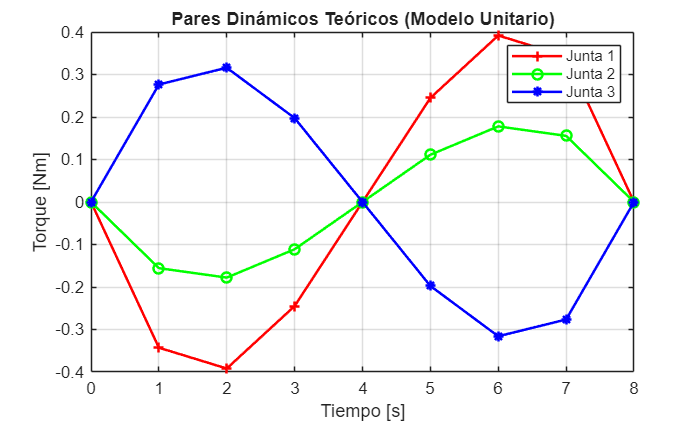

%% CÁLCULO DE DINÁMICA Y POTENCIA 

% 1. Definición de Parámetros (Modelo Unitario) por que en nuestro URDF
% esta definido asi
m2 = 1; I1 = 1; I2 = 1; I3 = 1;
% Aseguramos que L1 sea el valor correcto (por si acaso)
L1 = 0.45; 

% Inicializar vectores para guardar resultados
tao_1_c = zeros(1, length(tsim));
tao_2_c = zeros(1, length(tsim));
tao_3_c = zeros(1, length(tsim));
pot_total = zeros(1, length(tsim));
pot_1 = zeros(1, length(tsim));
pot_2 = zeros(1, length(tsim));
pot_3 = zeros(1, length(tsim));

% 2. Bucle de Cálculo
for i = 1 : length(tsim)
    
    % Recuperar cinemática (Velocidad y Aceleración)
    % Usamos las variables vectoriales ya calculadas arriba
    theta_1_vc = theta_1_P_v(i);
    theta_2_vc = theta_2_P_v(i);
    theta_3_vc = theta_3_P_v(i);

    acel_1 = theta_1_P_a(i);
    acel_2 = theta_2_P_a(i);
    acel_3 = theta_3_P_a(i);
    
    % Matriz de Inercia M(q) simplificada para SCARA 
    M11 = I1 + I2 + m2*(L1^2); 
    M12 = I2;
    M22 = I2;
    
    % Ecuación de Par: Torque = M * Aceleración
    tao_1_c(i) = M11 * acel_1 + M12 * acel_2;
    tao_2_c(i) = M12 * acel_1 + M22 * acel_2;
    tao_3_c(i) = I3 * acel_3;
    
    % Ecuación de Potencia: P = |Torque * Velocidad|
    pot_1(i) = abs(tao_1_c(i) * theta_1_vc);
    pot_2(i) = abs(tao_2_c(i) * theta_2_vc);
    pot_3(i) = abs(tao_3_c(i) * theta_3_vc);
    
    pot_total(i) = pot_1(i) + pot_2(i) + pot_3(i);
end

% 3. Generación de Gráficas 

% Gráfica de TORQUES
figure;
plot(tsim, tao_1_c, 'r-+', 'LineWidth', 1.5); hold on;
plot(tsim, tao_2_c, 'g-o', 'LineWidth', 1.5);
plot(tsim, tao_3_c, 'b-*', 'LineWidth', 1.5);
hold off;
title('Pares Dinámicos Teóricos (Modelo Unitario)');
xlabel('Tiempo [s]');
ylabel('Torque [Nm]');
legend('Junta 1', 'Junta 2', 'Junta 3');
grid on;

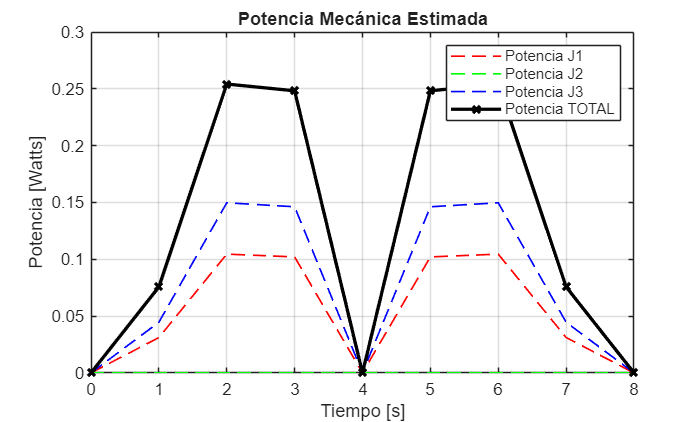


% Gráfica de POTENCIA (J/s)
figure;
plot(tsim, pot_1, 'r--', 'LineWidth', 1); hold on;
plot(tsim, pot_2, 'g--', 'LineWidth', 1);
plot(tsim, pot_3, 'b--', 'LineWidth', 1);
plot(tsim, pot_total, 'k-x', 'LineWidth', 2); % Total más gruesa
hold off;
title('Potencia Mecánica Estimada');
xlabel('Tiempo [s]');
ylabel('Potencia [Watts]');
legend('Potencia J1', 'Potencia J2', 'Potencia J3', 'Potencia TOTAL');
grid on;

### Datos para usar en simulacion en ROS2

%% --- GENERADOR DE CONFIGURACIÓN PARA ROS 2 (SALIDA UNIFICADA) ---
% Esta sección extrae los datos y genera un solo bloque de texto limpio.

% 1. Extracción de datos en vectores para facilitar el manejo
q_start = [theta_1_P(1), theta_2_P(1), theta_3_P(1)];
q_end   = [theta_1_P(end), theta_2_P(end), theta_3_P(end)];
tf_val  = tsim(end);

% 2. Construcción del mensaje usando sprintf (Formato en una sola variable)

mensaje_python = sprintf([ ...
    '================================================================\n', ...
    '   >>>  Datos para usar en nuestra configuracion y simulacion del roboto SCARA: trayectoria_scara.py  <<<   \n', ...
    '================================================================\n', ...
    '\n', ...
    '        # --- PARÁMETROS GENERADOS DESDE MATLAB LIVE SCRIPT ---\n', ...
    '        # Tiempo de trayectoria\n', ...
    '        self.tf      = %.1f\n', ...
    '\n', ...
    '        # Ángulos Iniciales [J1, J2, J3] (Radianes)\n', ...
    '        self.q_init  = [%.5f, %.5f, %.5f]\n', ...
    '\n', ...
    '        # Ángulos Finales [J1, J2, J3] (Radianes)\n', ...
    '        self.q_final = [%.5f, %.5f, %.5f]\n', ...
    '\n', ...
    '================================================================' ...
    ], tf_val, q_start(1), q_start(2), q_start(3), q_end(1), q_end(2), q_end(3));

% 3. Mostrar el resultado final (Una sola salida limpia)
disp(mensaje_python);

   >>>  Datos para usar en nuestra configuracion y simulacion del roboto SCARA: trayectoria_scara.py  <<<   

        # --- PARÁMETROS GENERADOS DESDE MATLAB LIVE SCRIPT ---
        # Tiempo de trayectoria
        self.tf      = 8.0

        # Ángulos Iniciales [J1, J2, J3] (Radianes)
        self.q_init  = [1.49214, 0.96039, -3.23793]

        # Ángulos Finales [J1, J2, J3] (Radianes)
        self.q_final = [-0.53175, 0.96039, 0.35675]



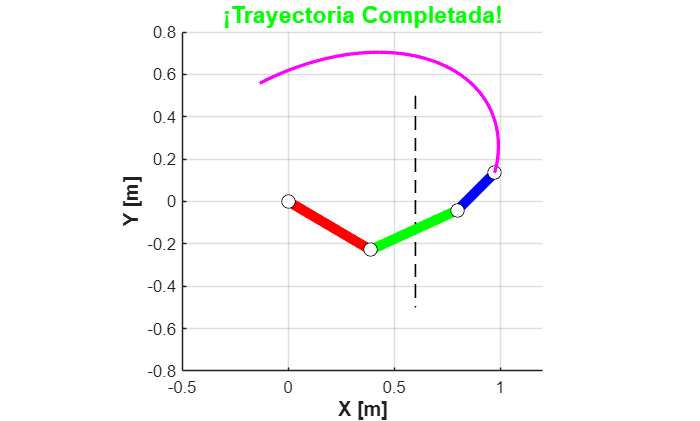

%% --- ANIMACIÓN CINEMATOGRÁFICA (CÁMARA LENTA & HOME) ---
% Este bloque crea una visualización de alta calidad para el video de evidencia.

% 1. Configuración de "Alta Resolución" para suavidad
% Generamos pasos muy finos (cada 0.05s) para que no se vea a saltos
dt_anim = 0.05; 
t_anim = 0 : dt_anim : tf; 

% 2. Recalcular el Polinomio suavemente (Solo para visualización)
q1_anim = zeros(1, length(t_anim));
q2_anim = zeros(1, length(t_anim));
q3_anim = zeros(1, length(t_anim));

for k = 1:length(t_anim)
    % Fórmula del Polinomio de 5to Grado
    tau = t_anim(k) / tf;
    poly = 10*tau^3 - 15*tau^4 + 6*tau^5;
    
    % Interpolamos desde tus ángulos INICIALES a FINALES
    q1_anim(k) = theta_1_in + poly * (theta_1_fin - theta_1_in);
    q2_anim(k) = theta_2_in + poly * (theta_2_fin - theta_2_in);
    q3_anim(k) = theta_3_in + poly * (theta_3_fin - theta_3_in);
end

% 3. Preparar el Escenario
figure('Name', 'Simulación SCARA - Cámara Lenta', 'Color', 'w');
grid on; axis equal;
xlabel('X [m]', 'FontSize', 12, 'FontWeight', 'bold');
ylabel('Y [m]', 'FontSize', 12, 'FontWeight', 'bold');
title('Inicializando Robot...', 'FontSize', 14);

% Límites fijos para que la cámara no se mueva
limite = L1 + L2 + L3 + 0.2;
xlim([-0.5, 1.2]);
ylim([-0.8, 0.8]);
hold on;

% Dibujar la meta (Trayectoria deseada)
if exist('x_P', 'var')
    plot(x_P, y_P, 'k--', 'LineWidth', 1, 'DisplayName', 'Trayectoria');
end

% Crear los objetos gráficos del robot (Eslabones gruesos)
h_L1 = plot([0,0], [0,0], 'r-', 'LineWidth', 6); % Hombro (Rojo)
h_L2 = plot([0,0], [0,0], 'g-', 'LineWidth', 6); % Codo (Verde)
h_L3 = plot([0,0], [0,0], 'b-', 'LineWidth', 6); % Muñeca (Azul)
h_joints = plot(0,0, 'ko', 'MarkerSize', 8, 'MarkerFaceColor', 'w'); % Articulaciones
h_trail = plot(0,0, 'm-', 'LineWidth', 2); % Rastro magenta

trail_x = []; trail_y = [];

% --- ESCENA 1: POSICIÓN HOME (BRAZO ESTIRADO) ---
% Mostramos al robot en q=[0, 0, 0] (Recto sobre eje X)
title('POSICIÓN HOME (Brazo Estirado)', 'Color', 'b');

% Coordenadas Home
hx0=0; hy0=0;
hx1=L1; hy1=0;
hx2=L1+L2; hy2=0;
hx3=L1+L2+L3; hy3=0;

% Dibujar Home
set(h_L1, 'XData', [hx0, hx1], 'YData', [hy0, hy1]);
set(h_L2, 'XData', [hx1, hx2], 'YData', [hy1, hy2]);
set(h_L3, 'XData', [hx2, hx3], 'YData', [hy2, hy3]);
set(h_joints, 'XData', [hx0, hx1, hx2, hx3], 'YData', [hy0, hy1, hy2, hy3]);

% ¡PAUSA DRAMÁTICA! (3 segundos para que expliques "Aquí inicia en Home")
pause(3.0); 

% --- ESCENA 2: EJECUCIÓN DE TRAYECTORIA (MUY LENTA) ---
for k = 1:length(t_anim)
    q1 = q1_anim(k);
    q2 = q2_anim(k);
    q3 = q3_anim(k);
    
    % Cinemática Directa
    x0=0; y0=0;
    x1 = L1 * cos(q1);
    y1 = L1 * sin(q1);
    x2 = x1 + L2 * cos(q1 + q2);
    y2 = y1 + L2 * sin(q1 + q2);
    x3 = x2 + L3 * cos(q1 + q2 + q3);
    y3 = y2 + L3 * sin(q1 + q2 + q3);
    
    % Actualizar Dibujo
    set(h_L1, 'XData', [x0, x1], 'YData', [y0, y1]);
    set(h_L2, 'XData', [x1, x2], 'YData', [y1, y2]);
    set(h_L3, 'XData', [x2, x3], 'YData', [y2, y3]);
    set(h_joints, 'XData', [x0, x1, x2, x3], 'YData', [y0, y1, y2, y3]);
    
    % Rastro
    trail_x = [trail_x, x3];
    trail_y = [trail_y, y3];
    set(h_trail, 'XData', trail_x, 'YData', trail_y);
    
    % Título dinámico
    title(sprintf('Ejecutando Trayectoria: %.2f / %.2f s', t_anim(k), tf), 'Color', 'k');
    
    % CONTROL DE VELOCIDAD
    drawnow;
    % Aumenta este número si la quieres AÚN MÁS LENTA
    pause(0.1); 
end

title('¡Trayectoria Completada!', 'Color', 'g');
hold off;

xlim([-0.50 1.20])
ylim([-0.80 0.80])